Definizione del **numeratore** e del **denominatore** della **FdT**.

num = [1 1];
den = conv(conv([1 0], [1 2]), conv([1 4], [1 4])); % conv usata per moltiplicare polinomi

sys = tf(num,den)


sys =
 
             s + 1
  ----------------------------
  s^4 + 10 s^3 + 32 s^2 + 32 s
 
Continuous-time transfer function.
Model Properties


Tracciamento del **luogo delle radici positivo**.

- Per valori non troppo elevati di K (con K > 0), i rami restano nel semipiano negativo e quindi i poli hanno parte reale negativa (sistema stabile).

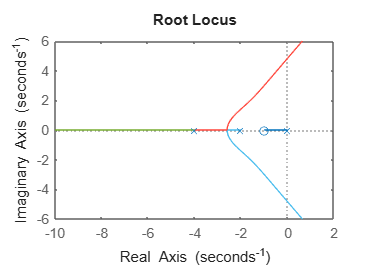

rlocus(num,den)

Tracciamento del **luogo delle radici negativo**.

- Per valori di K (con K < 0), non esiste alcun valore per la quale tutte le radici del denominatore siano a parte reale negativa. Per K  compreso tra "- infinito" e 0 c'è una radice che rimane nel semipiano destro.

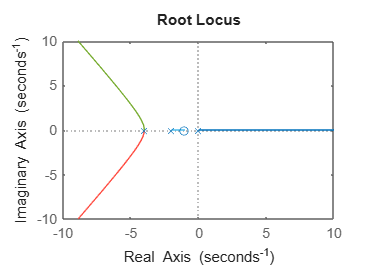

rlocus(-num,den)

Calcola e disegna il luogo delle radici di un sistema SISO ad anello aperto.

[r,k] = rlocus(sys);

r = 1.0e+02 *

   0.0000 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0003 + 0.0000i  -0.0003 + 0.0000i  -0.0004 + 0.0000i  -0.0004 + 0.0000i  -0.0005 + 0.0000i  -0.0006 + 0.0000i  -0.0006 + 0.0000i  -0.0006 + 0.0000i  -0.0006 + 0.0000i  -0.0007 + 0.0000i  -0.0009 + 0.0000i  -0.0011 + 0.0000i  -0.0012 + 0.0000i  -0.0015 + 0.0000i  -0.0018 + 0.0000i  -0.0021 + 0.0000i  -0.0024 + 0.0000i  -0.0029 + 0.0000i  -0.0034 + 0.0000i  -0.0039 + 0.0000i  -0.0045 + 0.0000i  -0.0051 + 0.0000i  -0.0058 + 0.0000i  -0.0064 + 0.0000i  -0.0069 + 0.0000i  -0.0074 + 0.0000i  -0.0078 + 0.0000i  -0.0082 + 0.0000i  -0.0085 + 0.0000i  -0.0087 + 0.0000i  -0.0089 + 0.0000i  -0.0091 + 0.0000i  -0.0093 + 0.0000i  -0.0094 + 0.0000i  -0.0095 + 0.0000i  -0.0096 + 0.0000i  -0.0096 + 0.0000i  -0.0097 + 0.0000i  -0.0097 + 0.0000i  -0.0098 + 0.0000i  -0.0098 + 0.0000i  -0.0099 + 0.0000i  -0.0099 + 0.0000i  -0.0099 + 0.0000i
  -0.0400 + 0.0000i  -0.0434 + 0.0

k = 1.0e+07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001
